# **Reflectron Correction - Grid points extraction of the calibration grid**

**This workflow colculates the individual grid points of the calibration grid for an atom probe. Prerequisite is dataset acquired with a grid "shadow mask" behind the electrode. After the grid points are extracted, the user can correct every dataset acquired with the atom probe.**

Prerequisite: Image Processing Toolbox in Matlab

## Constants definition

defines the constants

calibrationPara.GRIDPITCH = 0.2781228; %[mm] 
calibrationPara.FDMRESOLUTION = 512; % resolution of the FDM
 

## Data loading

Starting point is an *.epos file from a reflectron atom probe

[file, path] = uigetfile({'*.epos'},'Select an epos file');
fileName = [path file];
calibrationPara.path = path;
calibrationPara.file = file;
pos = posToTable(fileName);
 

### For the 6000 dataset - rotate the dataset around the z axis 60° degree

Create a rotation matrix

theta3 = deg2rad(60);
R3 = [cos(theta3) -sin(theta3); sin(theta3) cos(theta3)];

Rotate the pos file back

coordsPos = [pos.detx'; pos.dety'];
so3 = R3*coordsPos;
pos.detx = so3(1,:)';
pos.dety = so3(2,:)';
 

## Calculation of field desorption map

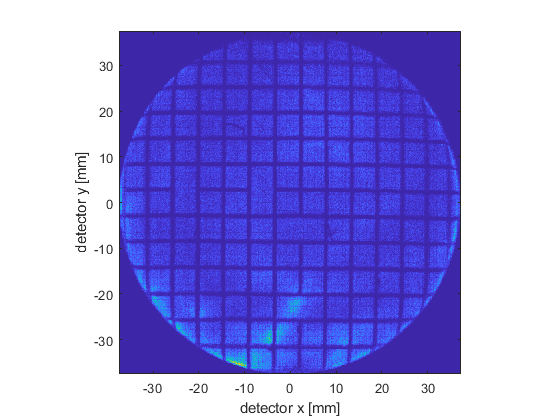

f = figure;
ax = axes;
calibrationPara.FDMRESOLUTION = 512; % number of pixels for the field desorption map
[FDM, FDMcenters] = hist3(double([pos.dety pos.detx]),'Nbins',[calibrationPara.FDMRESOLUTION calibrationPara.FDMRESOLUTION]);
FDMimage = imagesc(FDM,'XData',FDMcenters{1},'YData',FDMcenters{2});
axis equal;
axis tight;
xlabel 'detector x [mm]'
ylabel 'detector y [mm]'
ax.YDir = 'normal';
ax.XDir = 'normal';
hold on

## Edge extraction

find the optimum threshold value by changing it and visual observation. Important: the grid bar width should be seen in between the red lines and reduce the artefacts inside the squares

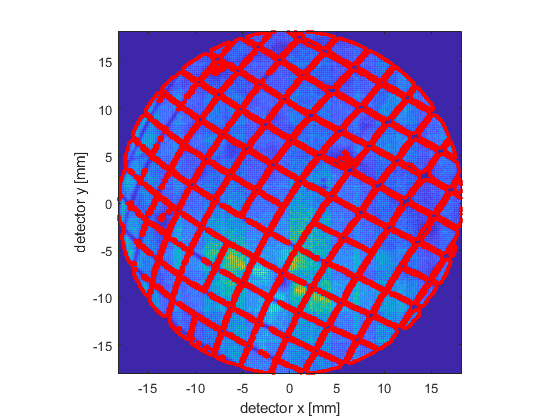

% find threshold value
calibrationPara.THRESHOLDFAC = 0.03; % to biarize the image for canny edge detection
threshold = max(FDM(:)) * calibrationPara.THRESHOLDFAC;
edgeBinary = edge(FDM > threshold,"canny");
[edgeY, edgeX] = find(edgeBinary);
edgeX = FDMcenters{1}(edgeX); edgeX = edgeX';% conversion from pixels to coordinates
edgeY = FDMcenters{2}(edgeY); edgeY = edgeY';% conversion from pixels to coordinates
s = scatter(edgeX,edgeY,'.r');

## Generation of patch object and export to .obj

Save the obj in a folder and continue with Blender

fv.vertices = [edgeX,edgeY,zeros(size(edgeX))];
fv.faces = [];
% save object
objName = 'Test_4000_01';
objFileName = [objName '_reflectronCalibrationGridEdgesRaw.obj']; 
patchToObj(fv,objName,objFileName);

% if you want to save the calibration Parameter
% save('calibrationPara');

clearvars -except pos calibrationPara

 

## Clean up and identify individual grid lines in Blender

- Import .obj in Blender

            Important Forward Axis **X** & Up Axis **Z**

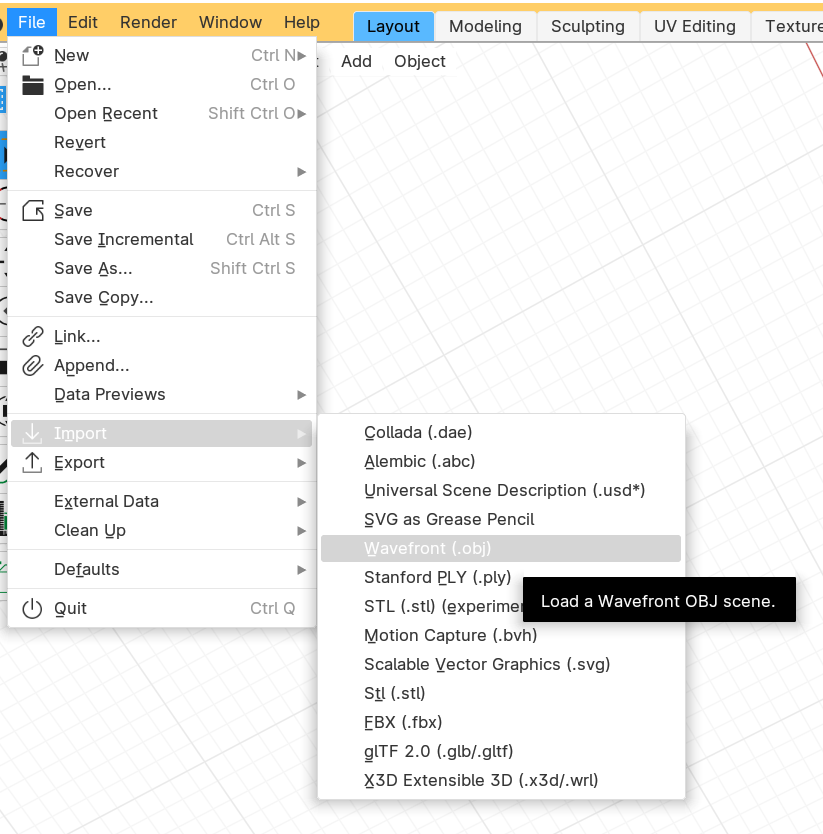                  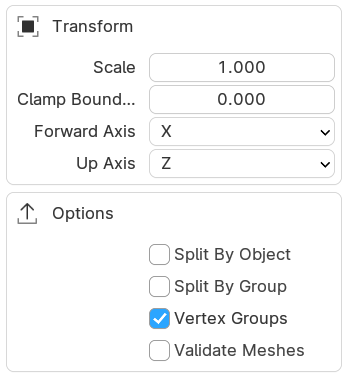     

- Edit Mode 

- 'C' -> circle selection - select lines - 'Esc' - 'P' > 'Selection' - new object 

- name objects along direction & index

- export as .obj

naming convention for edge objects in Blender: [linedirection lineIndex edgedirection] e.g.: X-1P, Y+0P

lineDirection... X or Y

lineIndex relative to to grid origin

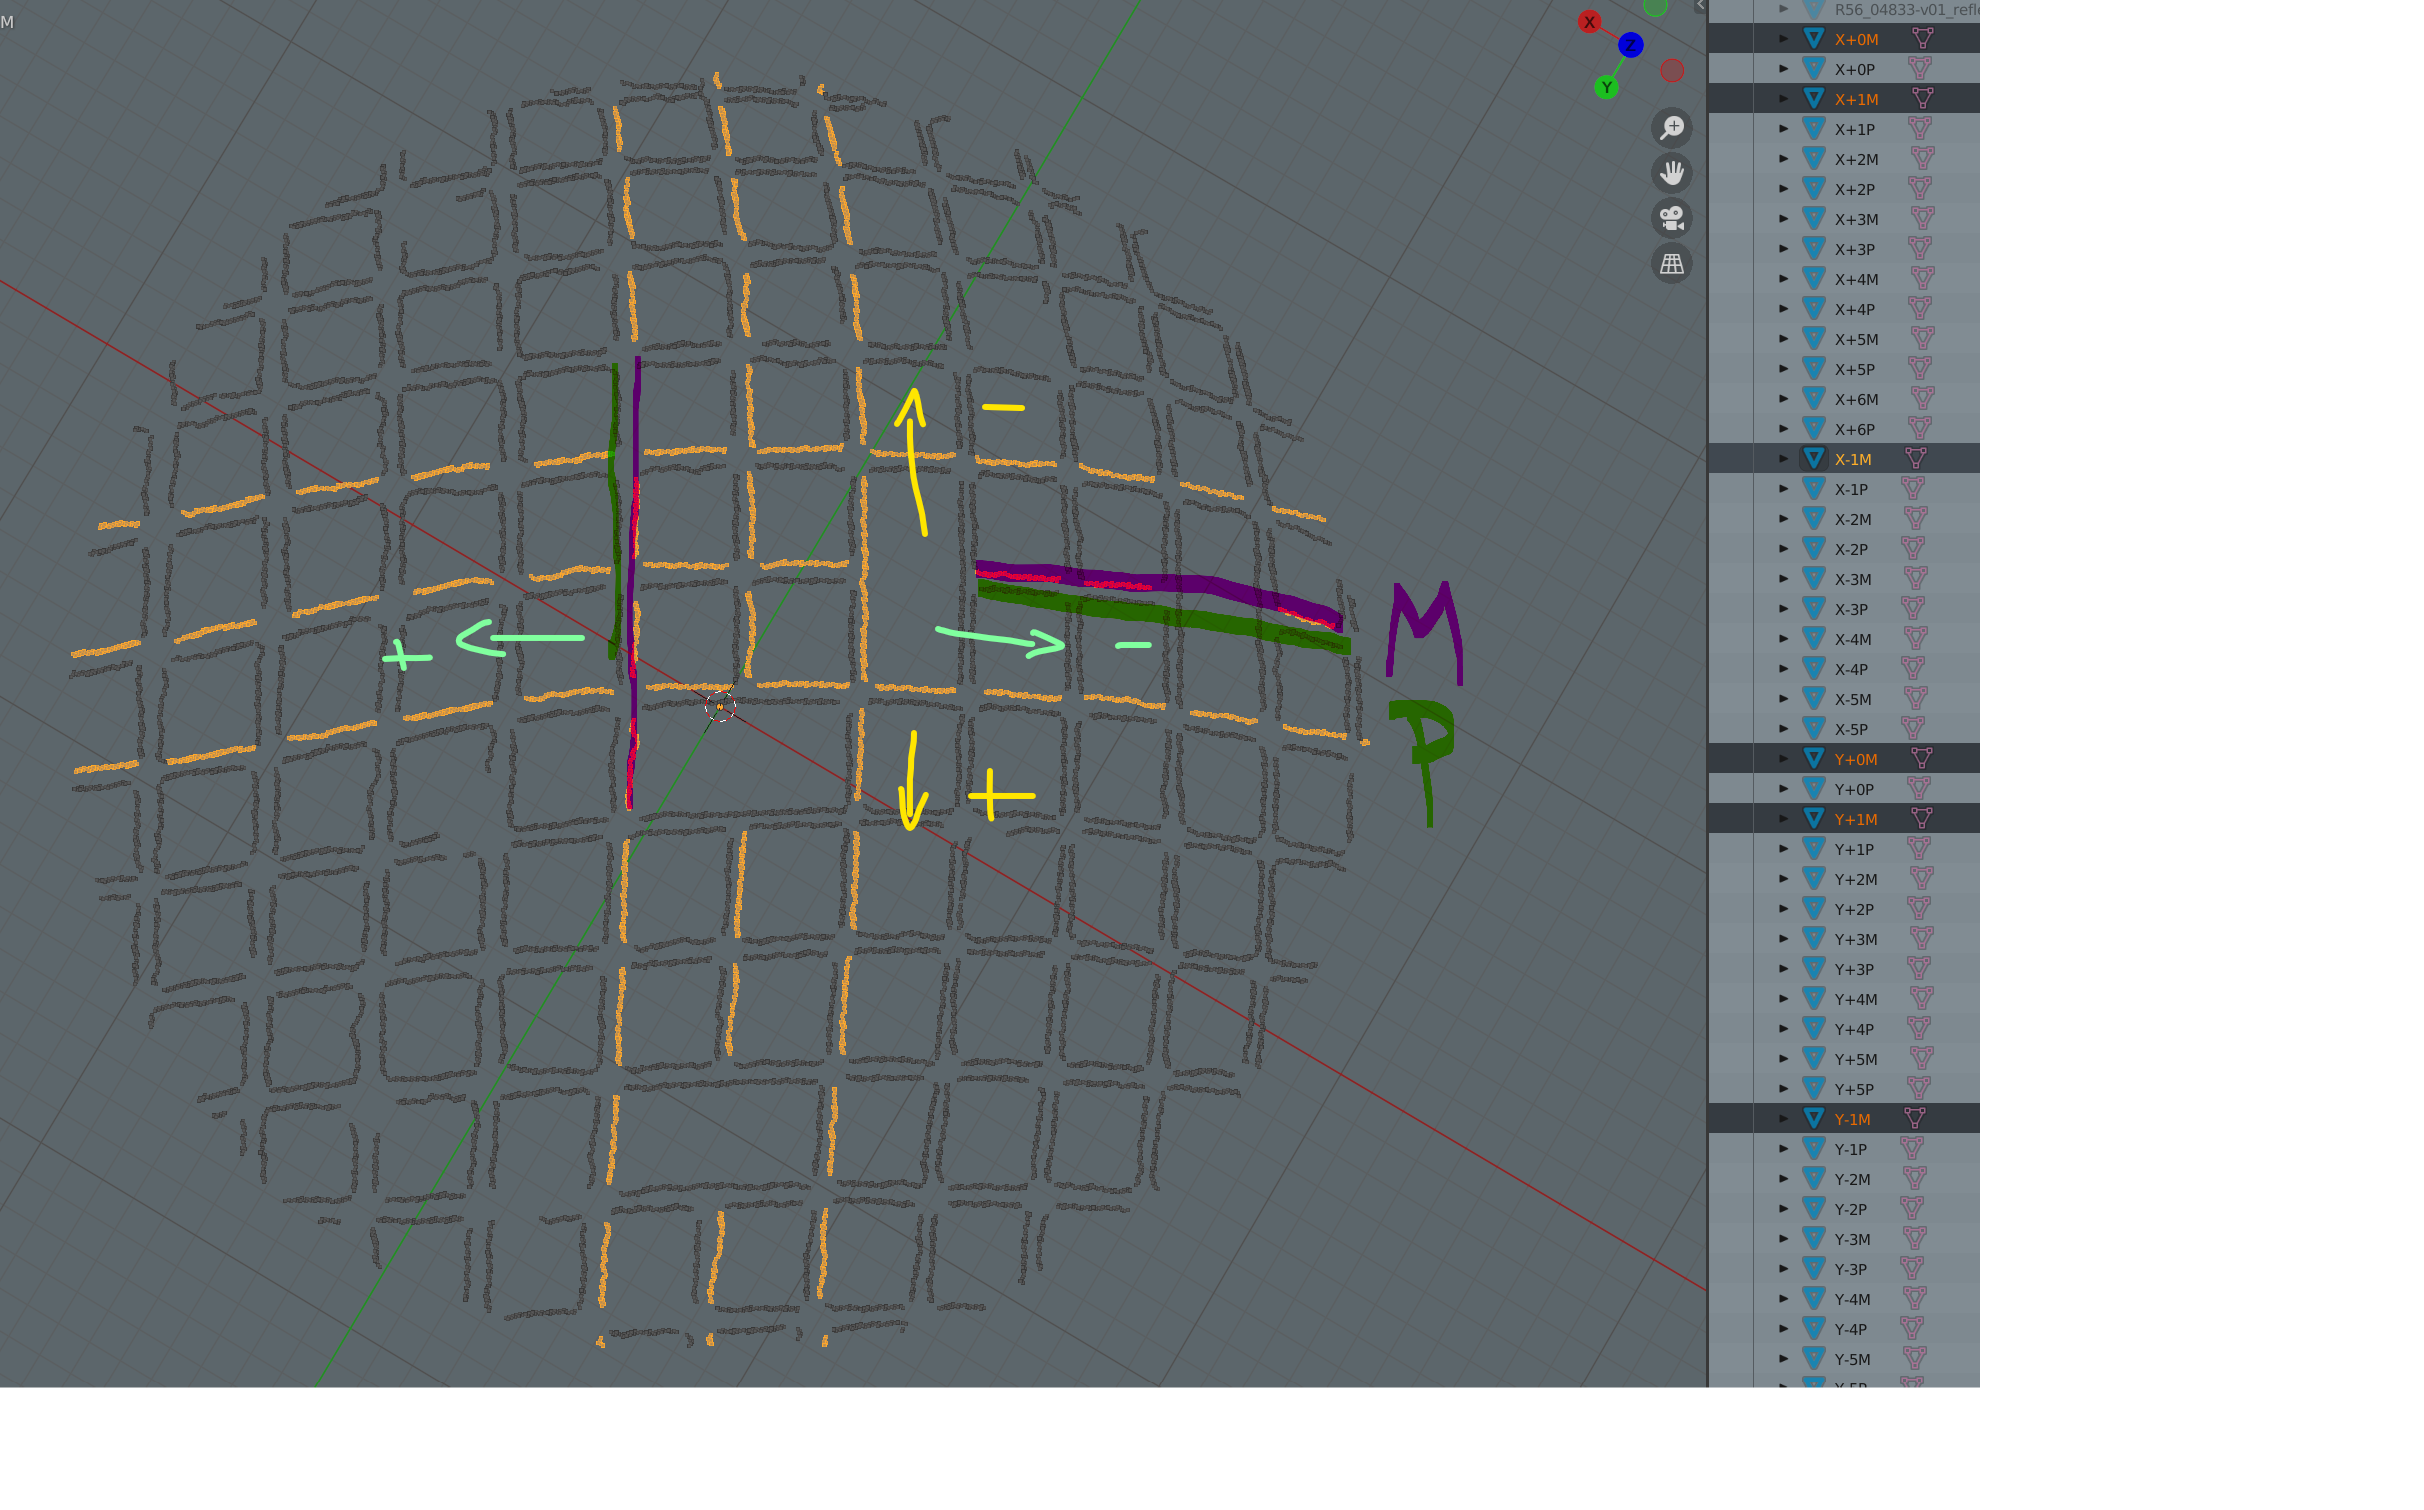

*Export it back as .obj for Matlab IMPORTANT - Forward Axis ****X**** & Up Axis ****Z***

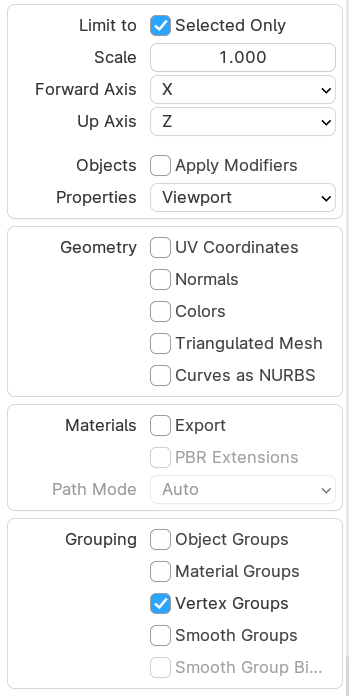

## Reimport of cleaned mesh 

import marked lines from Blender into Matlab

[objFile, objPath] = uigetfile({'*.obj'},'select obj file');
fileID = fopen([objPath objFile],'r');
formatSpec = '%c';
objText = string(fscanf(fileID,formatSpec));
objText = splitlines(objText);
objText(objText == "") = []; % remove empty lines
objStartIdx = find(startsWith(objText,"o"));
objEndIdx = [objStartIdx(2:end)-1; length(objText)];
objNames = extractBetween(objText(objStartIdx),3, 6);
xIdxRange = [0 0]; % ranges of indices that are encountered
yIdxRange = [0 0];


Preallocation and Extraction of single pointlines from the imported object

objects = cell(length(objNames),1);
 
for o = 1:length(objNames)
    verticesTMP = extractAfter(objText(objStartIdx(o)+1:objEndIdx(o)),2);
    vertices = zeros(length(verticesTMP),3);
    for v = 1:length(verticesTMP)
        vertices(v,:) = str2num(verticesTMP(v));
    end
    objects{o,1}.vertices = vertices;
    vertices = [];
    objects{o,1}.name = objNames(o);
    objects{o,1}.lineDirection = extractBetween(objNames(o),1, 1);
    objects{o,1}.lineIdx = str2num(extractBetween(objNames(o),2, 3));
    objects{o,1}.lineEdgeSide = extractBetween(objNames(o),4, 4);
    
    % calculate range of indices
    if strcmp(objects{o}.lineDirection, 'X')
        if objects{o}.lineIdx < xIdxRange(1)
            xIdxRange(1) = objects{o}.lineIdx;
        elseif objects{o}.lineIdx > xIdxRange(2)
            xIdxRange(2) = objects{o}.lineIdx;
        end
    else
        if objects{o}.lineIdx < yIdxRange(1)
            yIdxRange(1) = objects{o}.lineIdx;
        elseif objects{o}.lineIdx > yIdxRange(2)
            yIdxRange(2) = objects{o}.lineIdx;
        end
    end
end
clearvars -except objects pos calibrationPara

## Creating of fitAdvice

Take the marked object lines and fit a line to it with the fit function and the parameter Splinefittingparameter.

% You can plot the calculation but because of speed it is in comments.
calibrationPara.SPLINEFITTINGPARAMETER = 0.04;
% 3000 0.04
% 4000 0.04     
% 5000 Leoben 0.04 & fzero(fg,10)
% 5000 Oxford 0.01
% 6000 0.04
%%%% plot the fitting lines if you want to see the fits
% figure();
% ax = axes();
% hold on
for o=1:length(objects)
%     s(o) = scatter(objects{o}.vertices(:,1),objects{o}.vertices(:,2),'.');
%     s(o).DisplayName = objects{o}.name;
    [xData, yData] = prepareCurveData(objects{o}.vertices(:,1),objects{o}.vertices(:,2));
    ft = fittype( 'smoothingspline' );
    opts = fitoptions( 'Method', 'SmoothingSpline' );
    opts.SmoothingParam = calibrationPara.SPLINEFITTINGPARAMETER;
    [objects{o}.fit, objects{o}.gof] = fit( xData, yData, ft ,opts);
%     p(o) = plot(objects{o}.fit);
%     delete(p(o));
end
% hold on
% ax.XLim = [-20 20];
% ax.YLim = [-20 20];
% legend off

% split in lines for x and y directions
xLines = objects(cellfun(@(x) strcmp(x.lineDirection, 'X'),objects));
yLines = objects(cellfun(@(x) strcmp(x.lineDirection, 'Y'),objects));
clearvars -except objects pos calibrationPara xData xLines yData yLines

## Finding intersection points between lines

The intersection point of the fitted lines in X and Y direction are now calculated for each intersection point of the actual mesh. Each point of the mesh has 4 sourrunding points from the crossing of the M and P lines of the X and Y direction. From the four calculated points the actual mesh point position is calculated.

% preallocation
intersectionName = strings(length(xLines), length(yLines));
intersectionY = zeros(length(xLines), length(yLines));
intersectionX = zeros(length(xLines), length(yLines));

for xIdx = 1:length(xLines)
    for yIdx = 1:length(yLines)
        txt = xLines{xIdx}.name + yLines{yIdx}.name;
        intersectionName(xIdx,yIdx) = txt; 
        %%% intersection caclulation of the two fit curves
        % if the calculation does not fit, then change the splinefitting
        % parameter or adjust the second value of fzero(fg, 0) to a higher
        % or lower value until you get a satisfying result
        fg = @(x) (xLines{xIdx}.fit(x) - yLines{yIdx}.fit(x));
        intersectionY(xIdx,yIdx) = fzero(fg,0);
        intersectionX(xIdx,yIdx) = xLines{xIdx}.fit(intersectionY(xIdx,yIdx));
        
        
    end
end

% combine intersection corners to points and calculate distortion
gridIntersectionCornerName = erase(intersectionName,["M", "P"]);
gridIntersectionNamesList = unique(gridIntersectionCornerName);

% preallocation
detectorIntersectionX = zeros(length(gridIntersectionNamesList),1);
detectorIntersectionY = zeros(length(gridIntersectionNamesList),1);
numberOfCorners = zeros(length(gridIntersectionNamesList),1);
gridXIdx = zeros(length(gridIntersectionNamesList),1);
gridYIdx = zeros(length(gridIntersectionNamesList),1);
gridIntersectionX = zeros(length(gridIntersectionNamesList),1);
gridIntersectionY = zeros(length(gridIntersectionNamesList),1);

for i = 1:length(gridIntersectionNamesList)
    % calculate intersection coordinates on detector
    detectorIntersectionY(i,1) = mean(intersectionY(gridIntersectionCornerName == gridIntersectionNamesList(i)));
    detectorIntersectionX(i,1) = mean(intersectionX(gridIntersectionCornerName == gridIntersectionNamesList(i)));
    % scatter(detectorIntersectionX(i),detectorIntersectionY(i),'x');
    % text(detectorIntersectionX(i),detectorIntersectionY(i),gridIntersectionNamesList(i));
    numberOfCorners(i,1) = nnz(gridIntersectionCornerName == gridIntersectionNamesList(i));
    
    gridXIdx(i,1) = str2num(extractBetween(gridIntersectionNamesList(i),2,3));
    gridYIdx(i,1) = str2num(extractBetween(gridIntersectionNamesList(i),5,6));
    
    % claculate intersection coordinates on grid
    gridIntersectionX(i,1) = gridXIdx(i) * calibrationPara.GRIDPITCH;
    gridIntersectionY(i,1) = gridYIdx(i) * calibrationPara.GRIDPITCH;
     
end

% final positions of the intersections
intersections = table(gridIntersectionNamesList,gridXIdx, gridYIdx,...
    detectorIntersectionX,detectorIntersectionY,...
    numberOfCorners,...
    gridIntersectionX, gridIntersectionY,...
    'VariableNames',["intersection","xIdx","yIdx","detectorX","detectorY","corners","gridX","gridY"]);

intersections = sortrows(intersections,{'xIdx','yIdx'});
clearvars -except objects pos calibrationPara intersections intersectionX intersectionY
 

## Control if the calculation of the intersection worked

Control the calculated intersections points for the fitted lines.

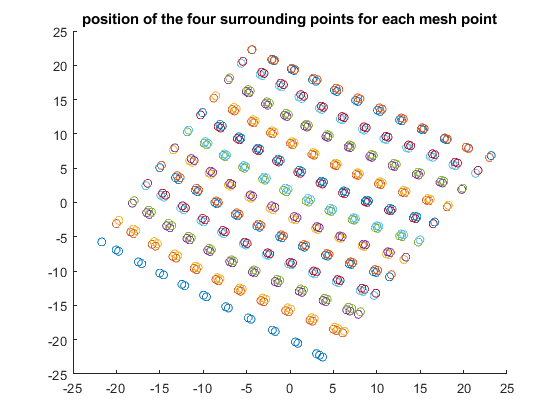

figure;
scatter(intersectionY, intersectionX)
title('position of the four surrounding points for each mesh point')

Check the entire mesh if it fits to your dataset and that you have no rotation in the datapoints

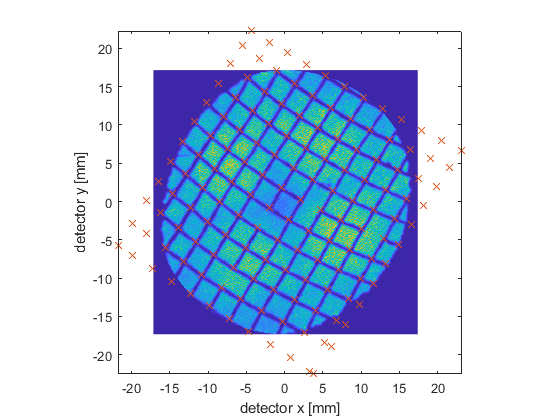

% plots FDM
figure;
ax = axes;
[FDM, FDMcenters] = hist3(double([pos.dety pos.detx]),'Nbins',[calibrationPara.FDMRESOLUTION calibrationPara.FDMRESOLUTION]);
FDMimage = imagesc(FDM,'XData',FDMcenters{1},'YData',FDMcenters{2});
axis equal;
axis tight;
xlabel 'detector x [mm]'
ylabel 'detector y [mm]'
ax.YDir = 'normal';
ax.XDir = 'normal';
hold on;
% adds the final intersection points
scatter(intersections.detectorY,intersections.detectorX, 'x', 'MarkerEdgeColor', [0.8500 0.3250 0.0980]);

Both images should look like this: 

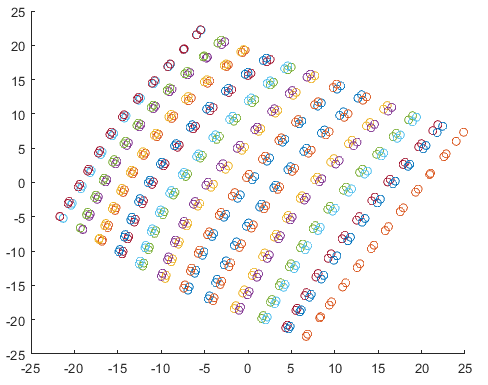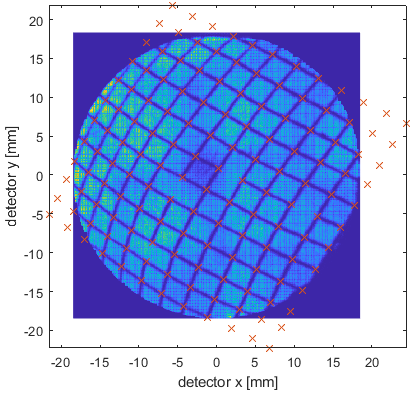

If it looks like this, you have to change the splinefitting parameter and/or the second value from fzero(fg,0)

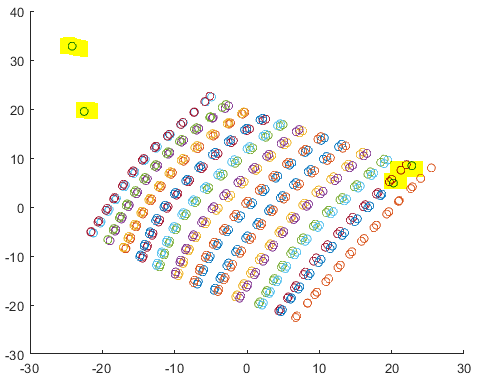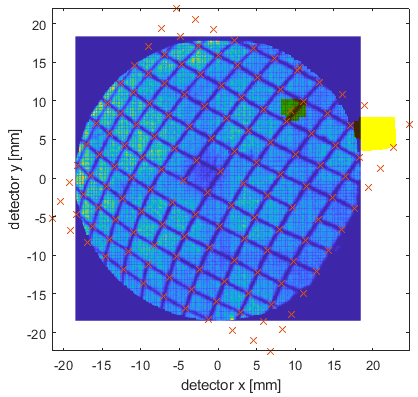

## Add the extrapolation for each row through the intersections in x direction and add the triangulation

% Parameters for Extrapolation
calibrationPara.extrapMode = 'linear';
calibrationPara.alpha = 10; % [mm] alpha value for triangulation
xIndices = sort(unique(intersections.xIdx));
yIndices = sort(unique(intersections.yIdx));

% x line extrapolation
for ix = 1:length(xIndices)
    xData = intersections.detectorX(intersections.xIdx == xIndices(ix));
    yData = intersections.detectorY(intersections.xIdx == xIndices(ix));
    xTmp = interp1(1:length(xData),xData,0:length(xData)+1,calibrationPara.extrapMode,'extrap');
    yTmp = interp1(1:length(yData),yData,0:length(yData)+1,calibrationPara.extrapMode,'extrap');
    detectorX = [xTmp(1); xTmp(end)];
    detectorY = [yTmp(1); yTmp(end)];
    xIdx = [xIndices(ix); xIndices(ix)];
    yIdx = [min(yIndices)-1; max(yIndices)+1];
    corners = [0;0];
    gridX = xIdx * calibrationPara.GRIDPITCH;
    gridY = yIdx * calibrationPara.GRIDPITCH;
    
    % Write correct name
    if yIdx(1)>=0
        y1Name = ['Y' '+' num2str(yIdx(1))];
    else
        y1Name = ['Y' num2str(yIdx(1))];
    end
    if yIdx(2)>=0
        y2Name = ['Y' '+' num2str(yIdx(2))];
    else
        y2Name = ['Y' num2str(yIdx(2))];
    end
    if xIndices(ix)>=0
        xName = ['X' '+' num2str(xIndices(ix))];
    else
        xName = ['X' num2str(xIndices(ix))];
    end
    names =[string([xName y1Name]);...
        string([xName y2Name])];
    
    % create table with properties of extrapolated points
    tblTmp = table(names,xIdx, yIdx,...
    detectorX,detectorY,...
    corners,...
    gridX, gridY,...
    'VariableNames',["intersection","xIdx","yIdx","detectorX","detectorY","corners","gridX","gridY"]);
    intersections = [intersections; tblTmp];
end

clearvars -except objects pos calibrationPara intersections yIndices xIndices xData xLines yData yLines

## Add the extrapolation in y direction to include the entire FDM

% y line extrapolation
for iy = 1:length(yIndices)
    xData = intersections.detectorX(intersections.yIdx == yIndices(iy));
    yData = intersections.detectorY(intersections.yIdx == yIndices(iy));
    xTmp = interp1(1:length(xData),xData,0:length(xData)+1,calibrationPara.extrapMode,'extrap');
    yTmp = interp1(1:length(yData),yData,0:length(yData)+1,calibrationPara.extrapMode,'extrap');
    detectorX = [xTmp(1); xTmp(end)];
    detectorY = [yTmp(1); yTmp(end)];
    
    yIdx = [yIndices(iy); yIndices(iy)];
    xIdx = [min(xIndices)-1; max(xIndices)+1];
    corners = [0;0];
    gridX = xIdx * calibrationPara.GRIDPITCH;
    gridY = yIdx * calibrationPara.GRIDPITCH;
    
    
    if xIdx(1)>=0
        x1Name = ['X' '+' num2str(xIdx(1))];
    else
        x1Name = ['X' num2str(xIdx(1))];
    end
    if xIdx(2)>=0
        x2Name = ['X' '+' num2str(xIdx(2))];
    else
        x2Name = ['X' num2str(xIdx(2))];
    end
    if yIndices(iy)>=0
        yName = ['Y' '+' num2str(yIndices(iy))];
    else
        yName = ['Y' num2str(yIndices(iy))];
    end
    names =[string([x1Name yName]);...
        string([x2Name yName])];
    
    tblTmp = table(names,xIdx, yIdx, detectorX, detectorY, corners, gridX, gridY,...
    'VariableNames',["intersection","xIdx","yIdx","detectorX","detectorY","corners","gridX","gridY"]);
    intersections = [intersections; tblTmp];
end 
clearvars -except objects pos calibrationPara intersections
 

## **Save intersections - this is your transformation mesh & calibrationPara!**

### For the 6000 dataset back rotation of 60° 

Rotate the intersection detector points around 60°

theta1 = deg2rad(60);
R1 = [cos(theta1) -sin(theta1); sin(theta1) cos(theta1)];
coordsIntersections = [intersections.detectorX'; intersections.detectorY'];
so1 = R1*coordsIntersections;
intersections.detectorX = so1(1,:)';
intersections.detectorY = so1(2,:)';

Rotate the pos file back around -60°

theta2 = deg2rad(-60); % -90
R2 = [cos(theta2) -sin(theta2); sin(theta2) cos(theta2)];
coordsPos = [pos.detx'; pos.dety'];
so2 = R2*coordsPos;
pos.detx = so2(1,:)';
pos.dety = so2(2,:)';

Save the results!!

## Control your results

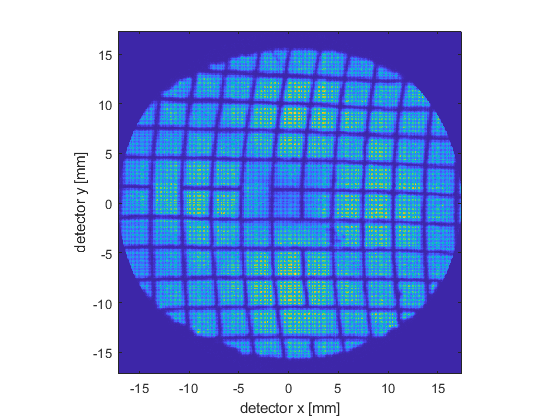

% plots FDM again
figure;
ax = axes;
[FDM, FDMcenters] = hist3(double([pos.dety pos.detx]),'Nbins',[calibrationPara.FDMRESOLUTION calibrationPara.FDMRESOLUTION]);
FDMimage = imagesc(FDM,'XData',FDMcenters{1},'YData',FDMcenters{2});
axis equal;
axis tight;
xlabel 'detector x [mm]'
ylabel 'detector y [mm]'
ax = gca;
ax.YDir = 'normal';
ax.XDir = 'normal';
hold on; 


% % Triangulation of the intersection points
% calibrationPara.alpha = 10;
% gridAlphaTrian = alphaTriangulation(alphaShape(intersections.detectorX,intersections.detectorY,calibrationPara.alpha));
% triplot(gridAlphaTrian,intersections.detectorY,intersections.detectorX,'g','LineWidth',.5);
% hold on
% % adds the intersection position of the mesh
% scatter(intersections.detectorY,intersections.detectorX,'r','LineWidth',.5);

 

## Translating a dataset into virtual detector coordinates

The user can now use this workflow to correct the data or use the Workflow_ReflectronCorrection_Dataset or the function posReflectronCorrected

loading the dataset to be translated

% [transPosName, transPosPath] = uigetfile({'*.epos'},'Select an epos file');
% transPosName
% transPosPath
% fileName = [transPosPath transPosName];
% transPos = posToTable(fileName);

Or use the one for extracting the grid to see if the correction worked

transPos = pos;

## Plot FDM before Translation

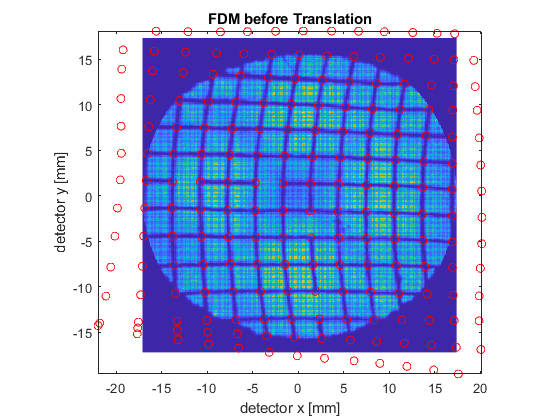

figure;
ax = axes;
[FDM, FDMcenters] = hist3(double([transPos.dety transPos.detx]),'Nbins',[calibrationPara.FDMRESOLUTION calibrationPara.FDMRESOLUTION]);
imagesc(FDM,'XData',FDMcenters{1},'YData',FDMcenters{2});
axis equal;
axis tight;
xlabel 'detector x [mm]'
ylabel 'detector y [mm]'
ax.YDir = 'normal';
ax.XDir = 'normal';
title('FDM before Translation')
hold on;
% % add the translation mesh
% gridAlphaTrian = alphaTriangulation(alphaShape(intersections.detectorX,intersections.detectorY,calibrationPara.alpha));
% triplot(gridAlphaTrian,intersections.detectorY,intersections.detectorX,'g','LineWidth',.5);
% hold on
% add the intersection points
scatter(intersections.detectorY,intersections.detectorX,'r','LineWidth',.5);

## Perform the Translation

tic; posCorrected = posReflectronCorrection(transPos, intersections); toc

Elapsed time is 24.579201 seconds.


## Plot FDM after Translation

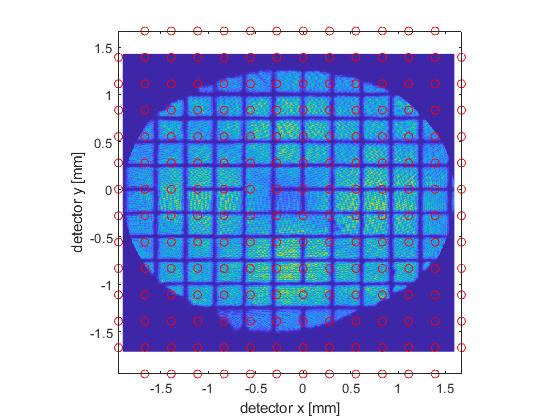

figure;
ax = axes;
[FDM, FDMcenters] = hist3(double([posCorrected.dety  posCorrected.detx]),'Nbins',[calibrationPara.FDMRESOLUTION calibrationPara.FDMRESOLUTION]);
imagesc(FDM,'XData',FDMcenters{1},'YData',FDMcenters{2});
axis equal;
axis tight;
xlabel 'detector x [mm]'
ylabel 'detector y [mm]'
ax.YDir = 'normal';
ax.XDir = 'normal';
hold on
% add the intersection grid points
scatter(intersections.gridX,intersections.gridY,'r','LineWidth',.5);

% hold on
% % add the corrected mesh
% calibrationPara.alpha = 10;
% gridAlphaTrian = alphaTriangulation(alphaShape(intersections.detectorX,intersections.detectorY,calibrationPara.alpha));
% triplot(gridAlphaTrian,intersections.gridY,intersections.gridX,'g','LineWidth',0.5);
% title('FDM after Translation')

 